## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

load('E2038.mat');   % Suppose data is in a variable pz
% % % % % % % % % % % % % % % % % % % % % % % 
%  Test Mean-subtraction to remove DC offset/baseline
dataTest1 = p(:,1) - mean(p(1:100,1));
dataTest2 = p(:,2) - mean(p(1:100,2));
dataTest3 = p(:,3) - mean(p(1:100,3));
dataTest4 = p(:,4) - mean(p(1:100,4));
dataTest5 = p(:,5) - mean(p(1:100,5));
dataTest6 = p(:,6) - mean(p(1:100,6));
dataTest7 = p(:,7) - mean(p(1:100,7));
dataTest8 = p(:,8) - mean(p(1:100,8));
dataTest9 = p(:,9) - mean(p(1:100,9));
dataTest10 = p(:,10) - mean(p(1:100,10));
dataTest11= p(:,11) - mean(p(1:100,11));
dataTest12 = p(:,12) - mean(p(1:100,12));
dataTest13 = p(:,13) - mean(p(1:100,13));
dataTest14 = p(:,14) - mean(p(1:100,14));
dataTest15 = p(:,15) - mean(p(1:100,15));
dataTest16 = p(:,16) - mean(p(1:100,16));
dataTest17 = p(:,17) - mean(p(1:100,17));

% % % % % % % % % % % % % % % % % % % % 
data = dataTest3*1000;    % Adjust column to your data of interest
Fs = fs;             % Sampling frequency in Hz
t = (0:length(data)-1)'/Fs;

%% Load Data
signal = data; % Your pressure-time data
N = length(signal);
fs = Fs; % Sampling frequency
t = (0:N-1)'/fs; % Time vector

%% Compute Fourier Transform (Restrict to Positive Frequencies)
fft_signal = abs(fft(signal));
frequencies = (0:floor(N/2)) * (fs/N); % Positive frequency spectrum
fft_signal = fft_signal(1:length(frequencies)); % Adjust FFT result

%% Identify Peaks in Spectrum
[pks, locs] = findpeaks(fft_signal, 'MinPeakHeight', 0.1*max(fft_signal));
% findpeaks(fft_signal,frequencies,'MinPeakProminence',4,'Annotate','extents')
boundaries = sort(frequencies(locs))' % Sort detected peak frequencies

boundaries =     86.5429e+000
   188.6918e+000
   195.7855e+000
   201.4604e+000
   205.7167e+000
   239.7663e+000
   248.2787e+000
   252.5349e+000
   255.3724e+000
   309.2843e+000


## Compare Frequency Content of Signals

A power spectrum displays the power present in each frequency. Spectral coherence identifies frequency-domain correlation between signals. Coherence values tending towards 0 indicate that the corresponding frequency components are uncorrelated while values tending towards 1 indicate that the corresponding frequency components are correlated. Consider two signals and their respective power spectra.

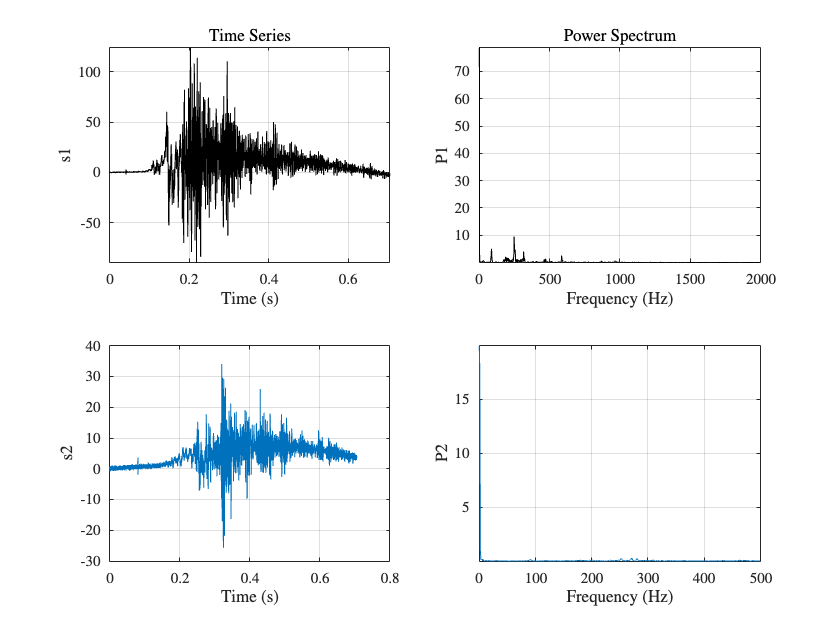

% Fs = FsSig;         % Sample Rate
sig1 = dataTest3*1000;%[mbar]
sig2 = dataTest10*1000;%[mbar]


[P1,f1] = periodogram(sig1,[],[],Fs,"power");
[P2,f2] = periodogram(sig2,[],[],Fs,"power");

figure
t = (0:numel(sig1)-1)/Fs;
subplot(2,2,1)
plot(t,sig1,"k")
ylabel("s1")
grid on
axis tight
xlabel("Time (s)")
title("Time Series")

subplot(2,2,3)
plot(t,sig2)
ylabel("s2")
grid on
xlabel("Time (s)")

subplot(2,2,2)
plot(f1,P1,"k")
ylabel("P1")
grid on
axis tight
title("Power Spectrum")
grid on
axis tight
xlim([0 2000])
xlabel("Frequency (Hz)")

subplot(2,2,4)
plot(f2,P2)
ylabel("P2")
grid on
axis tight
xlim([0 500])
xlabel("Frequency (Hz)")

% Define parameters
MaxNumPeaks = 25; % Number of peaks to detect
Fs = fs; % Replace with your actual sampling frequency

%EWT Method Peak Finding
        % Perform EWT on the selected test
        [mra_ewt, cfs, wfb, info] = ewt(dataTest3, 'MaxNumPeaks',MaxNumPeaks);
        % Convert peak frequencies and passbands to Hz
        PeakFrequencies = Fs * info.PeakFrequencies;
        freqPassbands = Fs * info.FilterBank.Passbands;

% Get signal length
N = length(dataTest3);

% Zero-pad FFT for better frequency resolution
NFFT = 2^nextpow2(N); % Next power of 2 for efficiency
f = (0:NFFT-1) * (Fs / NFFT); % Frequency axis

% Apply Hann window to reduce spectral leakage
w = hann(N); 
X = abs(fft(dataTest3 .* w, NFFT)); % Compute FFT with windowing
X = X(1:floor(NFFT/2)); % Keep only positive frequencies
f = f(1:floor(NFFT/2)); % Adjust frequency axis accordingly

% Detect peaks in FFT spectrum
[pks, locs] = findpeaks(X, 'MinPeakProminence', max(X) * 0.01, 'MinPeakDistance', 5);

% Sort peaks and select the top MaxNumPeaks
[sortedPks, sortIdx] = sort(pks, 'descend');
maxIdx = min(MaxNumPeaks, length(sortedPks)); % Ensure we do not exceed available peaks
peakLocs = locs(sortIdx(1:maxIdx)); % Get indices of the top peaks
peakFreqs = sort(f(peakLocs),'descend'); % Convert indices to actual frequency values

% Display detected peaks
disp('Detected Peak Frequencies (Hz) from FFT:');

Detected Peak Frequencies (Hz) from FFT:


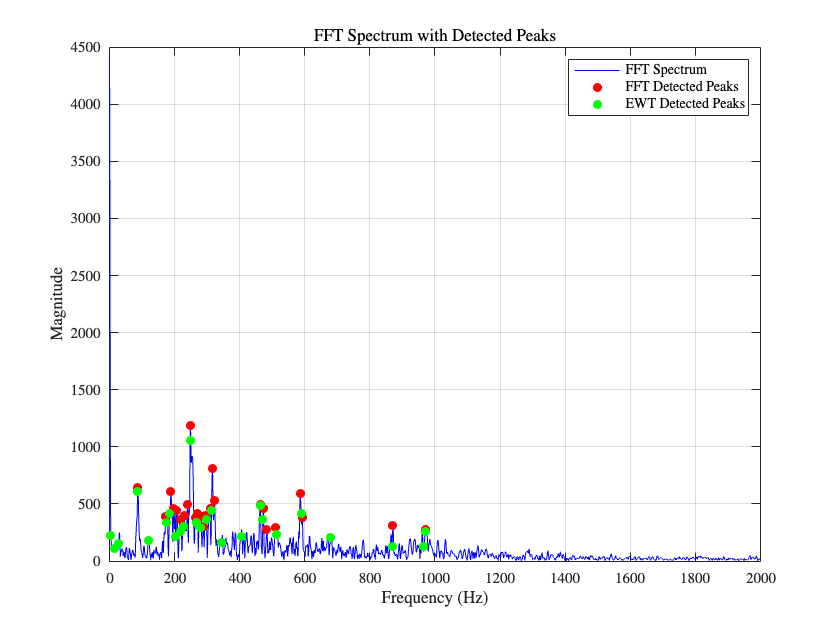

% disp(peakFreqs');

% Plot the FFT spectrum with detected peaks
figure;
plot(f, X, 'b'); hold on;
scatter(f(peakLocs), pks(sortIdx(1:maxIdx)), 'r', 'filled'); % Mark detected peaks
title('FFT Spectrum with Detected Peaks');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
legend('FFT Spectrum', 'Detected Peaks');

% Compare with EWT detected peaks
ewtPeaks = Fs * info.PeakFrequencies; % Extract EWT peaks
% disp('EWT Peak Frequencies (Hz):');
% disp(ewtPeaks);

% Overlay EWT peaks for visual comparison
scatter(ewtPeaks, interp1(f, X, ewtPeaks, 'linear'), 'g', 'filled'); % EWT peaks
xlim([0 2000])
legend('FFT Spectrum', 'FFT Detected Peaks', 'EWT Detected Peaks');

## dataDetrended

dataDetrended = detrend(dataTest16);
% Define parameters
MaxNumPeaks = 10; % Number of peaks to detect
Fs = fs; % Replace with your actual sampling frequency

%EWT Method Peak Finding
        % Perform EWT on the selected test
        [mra_ewt, cfs, wfb, info] = ewt(dataDetrended, 'MaxNumPeaks',MaxNumPeaks);
        % Convert peak frequencies and passbands to Hz
        PeakFrequencies = Fs * info.PeakFrequencies;
        freqPassbands = Fs * info.FilterBank.Passbands;

% Get signal length
N = length(dataDetrended);

% Zero-pad FFT for better frequency resolution
NFFT = 2^nextpow2(N); % Next power of 2 for efficiency
f = (0:NFFT-1) * (Fs / NFFT); % Frequency axis

% Apply Hann window to reduce spectral leakage
w = hann(N); 
X = abs(fft(dataDetrended .* w, NFFT)); % Compute FFT with windowing
X = X(1:floor(NFFT/2)); % Keep only positive frequencies
f = f(1:floor(NFFT/2)); % Adjust frequency axis accordingly

% Detect peaks in FFT spectrum
[pks, locs] = findpeaks(X, 'MinPeakProminence', max(X) * 0.05, 'MinPeakDistance', 5);

% Sort peaks and select the top MaxNumPeaks
[sortedPks, sortIdx] = sort(pks, 'descend');
maxIdx = min(MaxNumPeaks, length(sortedPks)); % Ensure we do not exceed available peaks
peakLocs = locs(sortIdx(1:maxIdx)); % Get indices of the top peaks
peakFreqs = sort(f(peakLocs),'descend'); % Convert indices to actual frequency values

% Display detected peaks
disp('Detected Peak Frequencies (Hz) from FFT:');

Detected Peak Frequencies (Hz) from FFT:


disp(peakFreqs');

   138.2504e+003
     3.5543e+003
     1.5411e+003
   326.1566e+000
   315.6662e+000
   255.5847e+000
   203.1326e+000
   195.5032e+000
    18.1198e+000
     1.9073e+000




% Plot the FFT spectrum with detected peaks
figure;
plot(f, X, 'b'); hold on;
scatter(f(peakLocs), pks(sortIdx(1:maxIdx)), 'r', 'filled'); % Mark detected peaks
title('FFT Spectrum with Detected Peaks');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
legend('FFT Spectrum', 'Detected Peaks');

% Compare with EWT detected peaks
ewtPeaks = Fs * info.PeakFrequencies; % Extract EWT peaks
disp('EWT Peak Frequencies (Hz):');

EWT Peak Frequencies (Hz):


disp(ewtPeaks);

     3.5539e+003
     1.5422e+003
   326.3092e+000
   316.3780e+000
   306.4469e+000
   283.7471e+000
   259.6286e+000
   195.7855e+000
    82.2867e+000
     9.9311e+000



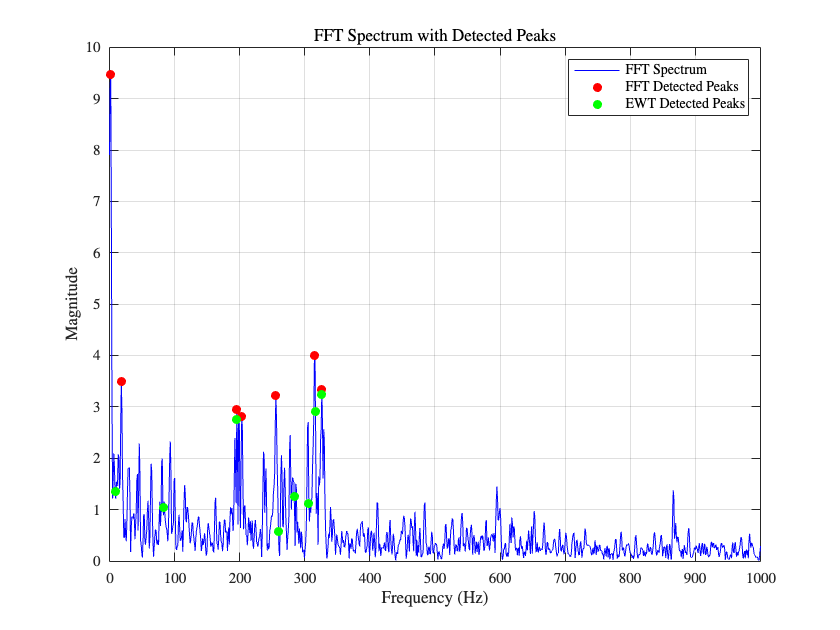


% Overlay EWT peaks for visual comparison
scatter(ewtPeaks, interp1(f, X, ewtPeaks, 'linear'), 'g', 'filled'); % EWT peaks
xlim([0 1000])
legend('FFT Spectrum', 'FFT Detected Peaks', 'EWT Detected Peaks');

% % Define parameters
% MaxNumPeaks = 5; % Number of peaks to detect
% Fs = fs; % Sampling frequency
% 
% % ===================== EWT METHOD PEAK FINDING =====================
% % Perform EWT on the selected test
% [mra_ewt, cfs, wfb, info] = ewt(dataTest3, 'MaxNumPeaks', MaxNumPeaks);
% 
% % Convert peak frequencies and passbands to Hz
% PeakFrequencies = Fs * info.PeakFrequencies;
% freqPassbands = Fs * info.FilterBank.Passbands;
% 
% % ===================== COMPUTE PERIODICOGRAM & MULTITAPER PSD =====================
% % Get signal length
% N = length(dataTest3);
% 
% % Compute Periodogram
% [Pxx_periodogram, f_periodogram] = periodogram(dataTest3, [], [], Fs);
% 
% % Compute Multitaper Power Spectral Density (EWT-aligned)
% [Pxx_mtm, f_mtm] = pmtm(dataTest3, 2, [], Fs,'Tapers','sine'); % Removed invalid 'Tapers' argument
% 
% % Normalize PSDs for peak detection
% Pxx_periodogram_norm = Pxx_periodogram / max(Pxx_periodogram);
% Pxx_mtm_norm = Pxx_mtm / max(Pxx_mtm);
% % 
% % [Pxx,F] = periodogram(dataTest3,[],[],Fs);
% % Pxxmt = pmtm(dataTest3,5,[],Fs,'Tapers','sine');
% % 
% % figure
% % subplot(2,1,1)
% % plot(F,Pxx)
% % title('Periodogram')
% % xlim([0 1000])
% % subplot(2,1,2)
% % plot(F,Pxxmt)
% % title('Smoothed Estimate')
% % xlim([0 1000])
% % xlabel('Frequency (Hz)')
% % hold off
% 
% 
% 
% % ===================== PEAK DETECTION IN MULTITAPER PSD =====================
% % Compute spectral bandwidth (for MinPeakDistance, EWT enforces this constraint)
% MinPeakDistance = round(((5 + 0.5) / (N + 1)) * length(f_mtm) * 0.5);  % Reduced by 50%
% 
% % Detect peaks in the multitaper PSD (lower threshold to detect more)
% threshold = 0.6; % Lowered to allow more peaks
% [pks, locs] = findpeaks(Pxx_mtm_norm, f_mtm, 'MinPeakHeight', threshold, 'MinPeakDistance', MinPeakDistance);
% 
% % ===================== FIXED SORTING & PEAK SELECTION =====================
% % Sort peaks by frequency (EWT prioritizes low frequencies)
% if ~isempty(pks)
%     [sortedLocs, sortIdx] = sort(locs, 'ascend'); % Sort in ascending order
%     maxIdx = min(MaxNumPeaks, length(sortedLocs)); % Limit to MaxNumPeaks
%     peakFreqs = sortedLocs(1:maxIdx); % Select the lowest MaxNumPeaks
% else
%     peakFreqs = [];
% end
% 
% % ===================== DISPLAY DETECTED PEAKS =====================
% disp('Detected Peak Frequencies (Hz) from Multitaper PSD:');
% disp(peakFreqs');
% 
% % ===================== PLOT PERIODICOGRAM VS MULTITAPER PSD =====================
% figure;
% 
% subplot(2,1,1)
% plot(f_periodogram, Pxx_periodogram_norm, 'b'); hold on;
% title('Periodogram Estimate')
% xlabel('Frequency (Hz)')
% xlim([0 1000]);
% ylabel('Normalized Power')
% 
% subplot(2,1,2)
% plot(f_mtm, Pxx_mtm_norm, 'b'); hold on;
% if ~isempty(peakFreqs)
%     scatter(peakFreqs, interp1(f_mtm, Pxx_mtm_norm, peakFreqs, 'linear'), 'r', 'filled'); % Mark detected peaks
% end
% title('Multitaper PSD with Detected Peaks')
% xlabel('Frequency (Hz)')
% ylabel('Normalized Power')
% grid on;
% legend('Multitaper PSD', 'Detected Peaks');
% 
% % ===================== COMPARE WITH EWT DETECTED PEAKS =====================
% ewtPeaks = Fs * info.PeakFrequencies; % Extract EWT peaks
% disp('EWT Peak Frequencies (Hz):');
% disp(ewtPeaks');
% 
% % Overlay EWT peaks for visual comparison
% if ~isempty(ewtPeaks)
%     scatter(ewtPeaks, interp1(f_mtm, Pxx_mtm_norm, ewtPeaks, 'linear'), 'g', 'filled'); % EWT peaks
%     xlim([0 1000]);
% end
% xlim([0 1000]); % Set limit for better visualization
% legend('Multitaper PSD', 'FFT-like Detected Peaks', 'EWT Detected Peaks');
% 
% 
% 
% 
% 


% % Define parameters
% MaxNumPeaks = 5; % Number of peaks to detect
% Fs = fs; % Sampling frequency
% 
% % ===================== EWT METHOD PEAK FINDING =====================
% % Perform EWT on the selected test
% [mra_ewt, cfs, wfb, info] = ewt(dataTest3, 'MaxNumPeaks', MaxNumPeaks);
% 
% % Convert peak frequencies and passbands to Hz
% PeakFrequencies = Fs * info.PeakFrequencies;
% freqPassbands = Fs * info.FilterBank.Passbands;
% 
% % ===================== MULTITAPER PSD ESTIMATION =====================
% % Compute Multitaper Power Spectral Density (EWT-aligned)
% [Pxx_mtm, f_mtm] = pmtm(dataTest3, 5, [], Fs);
% 
% % Log Spectrum Method (for dominant peak correction)
% Pxx_mtm_log = log(Pxx_mtm + 1);
% Pxx_mtm_norm = Pxx_mtm_log / max(Pxx_mtm_log); % Normalize
% 
% % Compute spectral bandwidth (for MinPeakDistance, EWT enforces this constraint)
% MinPeakDistance = round(((5 + 0.5) / (length(dataTest3) + 1)) * length(f_mtm));
% 
% % Detect peaks in the multitaper PSD
% threshold = 0.7 * max(Pxx_mtm_norm); % EWT uses 70% threshold
% [pks, locs] = findpeaks(Pxx_mtm_norm, f_mtm, 'MinPeakHeight', threshold, 'MinPeakDistance', MinPeakDistance);
% 
% % ===================== FIXED SORTING & PEAK SELECTION =====================
% % Sort peaks by frequency (EWT prioritizes low frequencies)
% if ~isempty(pks)
%     [sortedLocs, sortIdx] = sort(locs, 'ascend'); % Sort in ascending order
%     maxIdx = min(MaxNumPeaks, length(sortedLocs));
%     peakFreqs = sortedLocs(1:maxIdx);
% else
%     peakFreqs = [];
% end
% 
% % ===================== DISPLAY FINAL DETECTED PEAKS =====================
% disp('Final Detected Peak Frequencies (Hz) from Multitaper PSD:');
% disp(peakFreqs');
% 
% % ===================== PLOT MULTITAPER PSD WITH DETECTED PEAKS =====================
% figure;
% plot(f_mtm, Pxx_mtm_norm, 'b'); hold on;
% scatter(peakFreqs, interp1(f_mtm, Pxx_mtm_norm, peakFreqs, 'linear'), 'r', 'filled'); % Mark detected peaks
% title('Multitaper PSD with Detected Peaks');
% xlabel('Frequency (Hz)');
% ylabel('Normalized Power');
% grid on;
% legend('Multitaper PSD', 'Detected Peaks');
% 
% % ===================== COMPARE WITH EWT DETECTED PEAKS =====================
% ewtPeaks = Fs * info.PeakFrequencies; % Extract EWT peaks
% disp('EWT Peak Frequencies (Hz):');
% disp(ewtPeaks');
% 
% % Overlay EWT peaks for visual comparison
% if ~isempty(ewtPeaks)
%     scatter(ewtPeaks, interp1(f_mtm, Pxx_mtm_norm, ewtPeaks, 'linear'), 'g', 'filled'); % EWT peaks
% end
% xlim([0 1000]); % Set limit for better visualization
% legend('Multitaper PSD', 'FFT-like Detected Peaks', 'EWT Detected Peaks');







% Clear workspace and command window
% clear; clc; close all;

%% Load Pressure Signal Data
% % % % % % % % % % % % % % % % % % % % 
data = dataTest3;    % Adjust column to your data of interest
Fs = fs;             % Sampling frequency in Hz
t = (0:length(data)-1)'/Fs;
pressure = data;
%% Remove DC Offset
% pressure = pressure - mean(pressure);
%% Define Sampling Parameters
% Fs = 50000;  % Sampling frequency (Hz) - Modify based on your data
N = length(pressure); % Number of samples
dt = 1/Fs; % Time step
% t = (0:N-1)*dt; % Time vector (optional check)

%% Compute FFT
Y = fft(pressure); % Compute FFT
f = Fs * (0:(N/2))/N; % Frequency axis (only positive half)
P2 = abs(Y/N); % Two-sided amplitude spectrum
P1 = P2(1:N/2+1); % Single-sided spectrum


%% Convert to dB scale
P1_dB = 20 * log10(P1);

%% Apply Low-pass Filtering (Optional)
fc = 5000; % Cutoff frequency (Hz) - Adjust as needed
[b, a] = butter(4, fc/(Fs/2), 'low'); % 4th-order Butterworth filter
pressure_filt = filtfilt(b, a, pressure); % Apply filter

%% Compute FFT of Filtered Signal
Y_filt = fft(pressure_filt);
P2_filt = abs(Y_filt/N);
P1_filt = P2_filt(1:N/2+1);

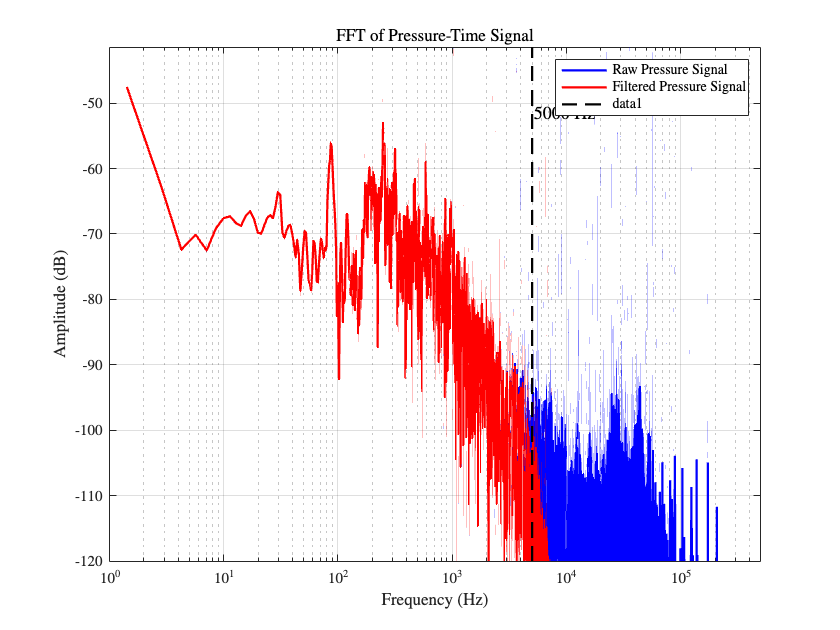

P1_filt_dB = 20 * log10(P1_filt);

%% Plot FFT Spectrum
figure;
semilogx(f, P1_dB, 'b', 'LineWidth', 1.5); hold on;
semilogx(f, P1_filt_dB, 'r', 'LineWidth', 1.5); % Plot filtered signal
xlabel('Frequency (Hz)');
ylabel('Amplitude (dB)');
title('FFT of Pressure-Time Signal');
legend('Raw Pressure Signal', 'Filtered Pressure Signal');
grid on;
xlim([1 max(f)]);
ylim([-120 max(P1_dB)]);

%% Mark Useful Signal and Cutoff Frequency
fc_marker = fc; % Adjust based on observation
line([fc_marker fc_marker], ylim, 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.5);
text(fc_marker, max(P1_dB)-10, sprintf('%d Hz', fc_marker), 'FontSize', 12, 'Color', 'k');

%% Define Sampling Parameters
Fs = double(Fs);  % Ensure Fs is floating-point
N = length(pressure); % Number of samples
dt = 1/Fs; % Time step
t = (0:N-1) * dt; % Time vector

%% Compute FFT
Y = fft(pressure); % Compute FFT
f = Fs * (0:(N/2)) / double(N); % Frequency axis (only positive half)
P2 = abs(Y/N); % Two-sided amplitude spectrum
P1 = P2(1:N/2+1); % Single-sided spectrum


%% Convert to dB scale
P1_dB = 20 * log10(max(P1, eps)); % Avoid log of zero

%% Apply Low-pass Filtering (Optional)
fc = 5000; % Cutoff frequency (Hz) - Adjust as needed
[b, a] = butter(4, fc/(Fs/2), 'low'); % 4th-order Butterworth filter
pressure_filt = filtfilt(b, a, pressure); % Apply filter

%% Compute FFT of Filtered Signal
Y_filt = fft(pressure_filt);
P2_filt = abs(Y_filt/N);
P1_filt = P2_filt(1:N/2+1);

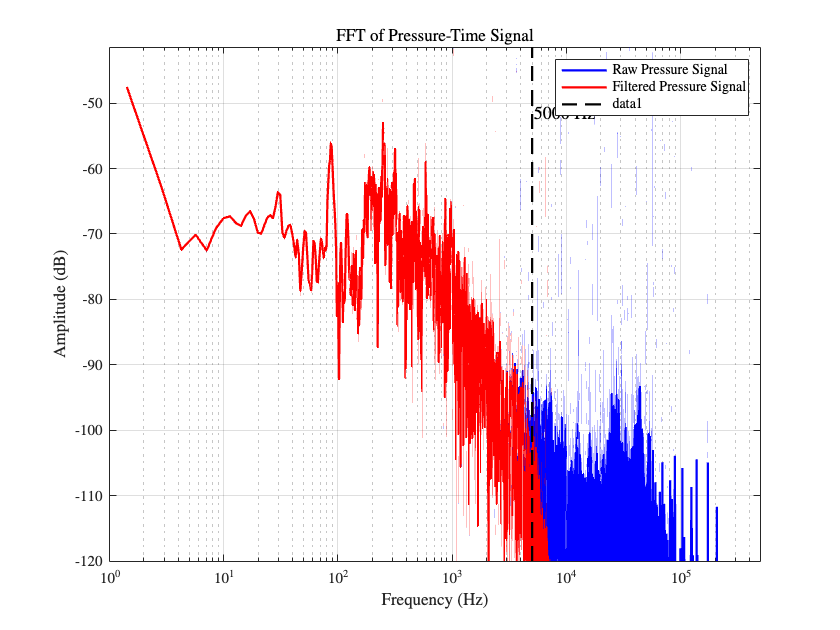

P1_filt_dB = 20 * log10(max(P1_filt, eps)); % Avoid log of zero

%% Plot FFT Spectrum
figure;
semilogx(f, P1_dB, 'b', 'LineWidth', 1.5); hold on;
semilogx(f, P1_filt_dB, 'r', 'LineWidth', 1.5); % Plot filtered signal
xlabel('Frequency (Hz)');
ylabel('Amplitude (dB)');
title('FFT of Pressure-Time Signal');
legend('Raw Pressure Signal', 'Filtered Pressure Signal');
grid on;
xlim([1 max(f)]);
ylim([-120 max(P1_dB)]);

%% Mark Useful Signal and Cutoff Frequency
fc_marker = fc; % Adjust based on observation
yLimits = ylim; % Fix ylim reference
line([fc_marker fc_marker], yLimits, 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.5);
text(fc_marker, max(P1_dB)-10, sprintf('%d Hz', fc_marker), 'FontSize', 12, 'Color', 'k');




%% Compute FFT
Y = fft(pressure);
P2 = abs(Y) / max(abs(Y)); % Normalize relative to max amplitude
P1 = P2(1:N/2+1); % Single-sided spectrum

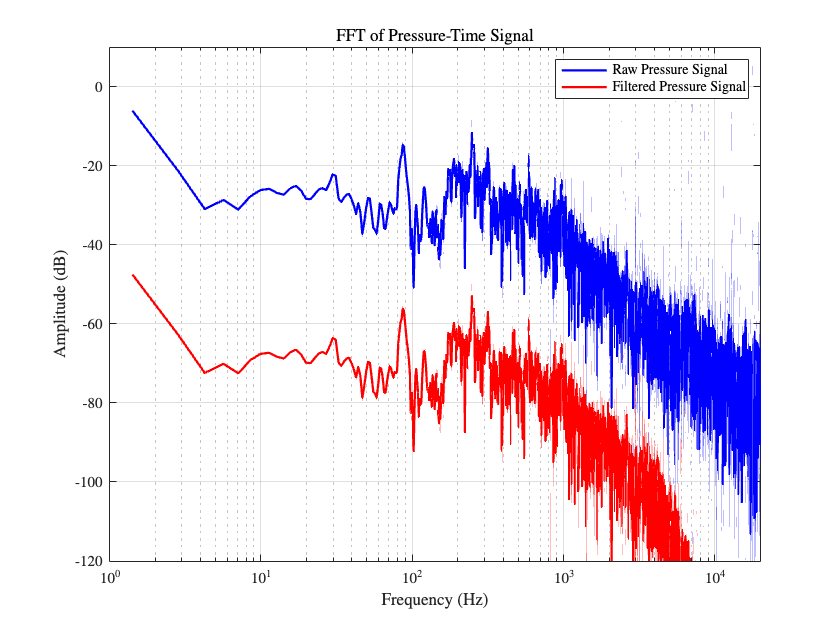

P1_dB = 20 * log10(max(P1, eps)); % Convert to dB

%% Plot FFT Spectrum
figure;
semilogx(f, P1_dB, 'b', 'LineWidth', 1.5); hold on;
semilogx(f, P1_filt_dB, 'r', 'LineWidth', 1.5); % Plot filtered signal
xlabel('Frequency (Hz)'); ylabel('Amplitude (dB)');
title('FFT of Pressure-Time Signal');
legend('Raw Pressure Signal', 'Filtered Pressure Signal');
grid on;
xlim([1 20000]); % Adjust to match reference plot
ylim([-120 10]); % Adjust y-limits for better visualization